# Power Spectra & Spectral Factorization

## Introduction

In this live script, we offer a few examples of solving, using MATLAB code, simple problems involving computation of the **power spectra** of stationary stochastic processes, the **spectral factorization** and the so-called **canonical spectral factorization**.

What you will learn:

- How to cope with a spectral factorization problem using MATLAB;

- How to manage a spectrum of a stochastic proces with the aim to obtain a canonical spectral factorization;

- How to evaluate the autocorrelation function of a stationary stochastic process, given its complex spectrum, and viceversa.

For a while we'll use the Symbolic Toolbox

clear variables
close all
clc

sympref('HeavisideAtOrigin', 1); % setting the Symbolic Toolbox

## **A Stationary Stochastic Process from a White Noise Response of an LTI Filter - A First Example**

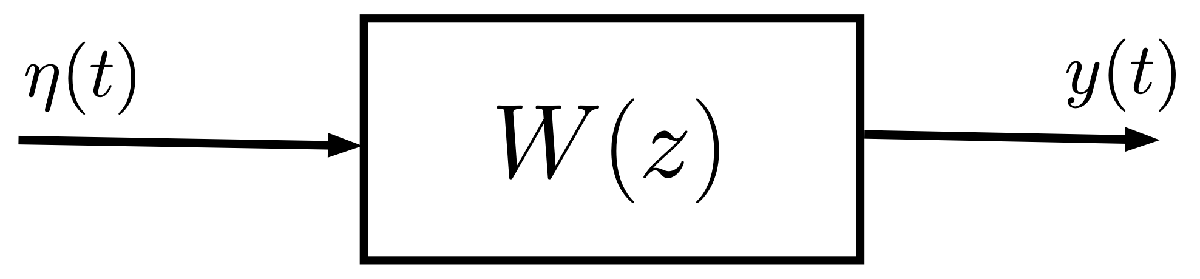

Consider a stationary stochastic process $y(t)$, generated by an LTI dynamic system with transfer function			

		
$$W(z) = \displaystyle \frac{1}{z-0.5}$$


Non e` una fattorizzazione canonica (grado num != grado den), dobbiamo applicare una trasformazione per rendere il teorema di fattorizzazione spettrale applicabile.

and white noise $\eta(t)$ as its input. Assume that  $\eta(t)$ has a zero-mean and a unitary variance: $\eta(\cdot) \sim \text{WN}(0,\,1)$

Find the power spectrum $\Gamma_y(\omega)$ and the autocorrelation function $\gamma_y(\tau)$ of $y(t)$.

### Solution

Since $y(t)$ is the output of the LTI system $W(z)$ (the filter) and the input is the unit-variance and zero-mean white noise $\eta(t)$, then the spectrum $\Phi(z)$ can be expressed as


$$\Phi_{y}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \Phi_{\eta}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot 1 = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) $$


syms z n

Wz = 1/(z-0.5)  % the LTI system

$$Wz = \frac{1}{-\frac{1}{2}+z}$$


sigma2_eta = 1; % the variance of the white noise 


Thus the process spectrum is

W_z1 = subs(Wz, z, (z^(-1))) % calcolo l'espressione con z^-1

$$W\_z1 = \frac{1}{\frac{1}{z}-\frac{1}{2}}$$

PhiZ = Wz*W_z1*sigma2_eta

$$PhiZ = \frac{1}{\left(\frac{1}{z}-\frac{1}{2}\right)\,\left(-\frac{1}{2}+z\right)}$$

Evaluating for $z=e^{i\,\omega$ we obtain $\Gamma_y(\omega)$

syms omega
Gamma_y = subs(PhiZ, z, exp(1i*omega)) % devo mettere l'esponenziale complesso

$$Gamma\_y = \frac{1}{\left({\mathrm{e}}^{-\omega \,\mathrm{i}}-\frac{1}{2}\right)\,\left({\mathrm{e}}^{\omega \,\mathrm{i}}-\frac{1}{2}\right)}$$

% Pero` fare il plotting di questo e` un casino, mi conviene usare le
% formule di eulero per far comparire seni e coseni

Rewrite $\Gamma_y(\omega)$ exploiting the Euler's formula	 				

			
$$e^{i\,\omega} = \cos \omega +i\,\sin \omega$$


where $i$ is the imaginary unit. Thus


$$\cos \omega = \displaystyle \frac{e^{i\,\omega}+e^{-i\,\omega}}{2}\quad $$


Gamma_y = simplify(rewrite(Gamma_y, "cos")) 

$$Gamma\_y = -\frac{4}{4\,\cos\left(\omega \right)-5}$$

The spectrum is

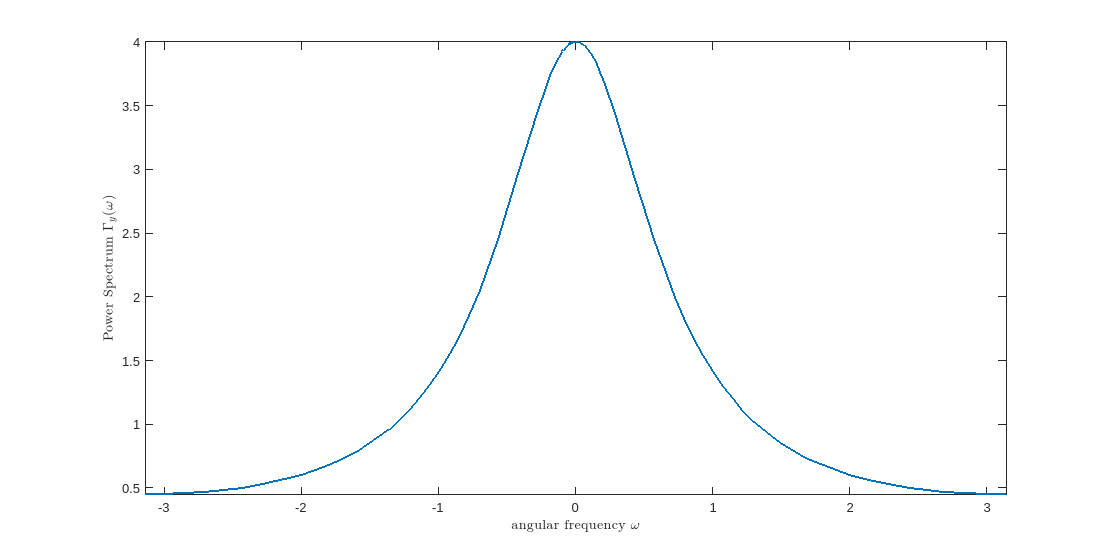

figure('Units','normalized','Position',[0.1,0.1,0.9,0.8]);
fplot(gca, Gamma_y, [-pi, pi], 'LineStyle','-','LineWidth',1.5); 
% plot the curve defined by the function y = Gamma_y(omega) over the
% interval [-pi , +pi]
xlabel('angular frequency $\omega$', 'Interpreter','latex');
ylabel('Power Spectrum $\Gamma_{y}(\omega)$', 'Interpreter','latex')

[betaX, alphaX] = numden(Wz);
betaPoly = sym2poly(betaX); % the coefficients of the numerator of the spectrum, as a symmetric polynomial
% betaPoly contains the floating-point description of the coefficients, 
% from the highest to the lowest degree monomial of the auxiliary variable x

alphaPoly = sym2poly(alphaX); % the coefficients of the denominator of the spectrum, as a symmetric polynomial
% alphaPoly contains the floating-point description of the coefficients, 
% from the highest to the lowest degree monomial of the auxiliary variable x

[r, Cz_coeffs, Az_coeffs] = L8_spectrFactAlg(betaPoly, alphaPoly)

r = -0.2500 - 0.9682i

Cz_coeffs = 1

Az_coeffs =    1.0000 + 0.0000i  -0.2500 - 0.9682i


% sort the display output of polynomial function in ascending order, i.e.
% according to the order of each monomial term
sympref('PolynomialDisplayStyle','ascend');

syms z1 % a trick to represent in a compact way 1/z

lambda2xi = sym(r) % the white noise spectrum

$$lambda2xi = -\frac{1}{4}-\frac{\sqrt{15}\,\mathrm{i}}{4}$$

Az1 = poly2sym(fliplr(Az_coeffs), z1) % the polynomial A(z) 

$$Az1 = 1+\left(-\frac{1}{4}-\frac{\sqrt{15}\,\mathrm{i}}{4}\right)\,z_{1}$$

Az = subs(Az1,z1,z^(-1))

$$Az = 1-\frac{\frac{1}{4}+\frac{\sqrt{15}\,\mathrm{i}}{4}}{z}$$

Cz1 = poly2sym(fliplr(Cz_coeffs), z1) % the polynomial C(z) 

$$Cz1 = 1$$

Cz = subs(Cz1,z1,z^(-1))

$$Cz = 1$$

Wz2 = Cz1/Az1 % the LTI system transfer function as symbolic object

$$Wz2 = -\frac{1}{-1+\left(\frac{1}{4}+\frac{\sqrt{15}\,\mathrm{i}}{4}\right)\,z_{1}}$$

W_z2 = tf(Cz_coeffs, Az_coeffs, 1, 'Variable','z^-1')

W_z2 =
 
             1
  -----------------------
  1 - (0.25+0.9682i) z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


a=1

a = 1

### Q&A

- **Q1**: Given the expression of $W(z)$,  to which family of rational spectrum processes does the analyzed stochastic process belong?

- AR(1)

- **Q2a**: Is the spectral factorisation canonical or not? **Q2b**: Why? **Q2c**: If not, what can the canonical spectral factorisation be?

- **A2a, A2b: **the spectral factorisation is not a canonical form, because there's no zero on the origin. To make it a canonical form, we have to multiply $z$ on the numerator of the transfer function. When I multiply $z$, it's the same as multiplying $e^{i \omega}$, which is a delay on the time space, but doesn't affect the shape of the frequency spectrum.

- **A2c**: the canonical spectral form is $\hat{W}(z)=\displaystyle \frac{z}{z-0.5} \quad \xi(\cdot) \sim \text{WN}(0, 1)$

- **Q3**: What is the variance of the process?

- **A3**: $\sigma_{y}^2 = \displaystyle \frac{1}{2\, \pi} \int_{-\pi}^{+\pi} \, \Gamma_y(\omega) \,d\omega$  or, exploiting the spectral canonical form $\sigma_{y}^2 = \displaystyle \frac{\lambda^2_{\xi}}{(1-a^2)} = \displaystyle \frac{1}{1-0.25} = \displaystyle \frac{4}{3}$

sigma2_y =  double((1/(2*pi))*int(Gamma_y,omega, [-pi,pi] ))

sigma2_y = 1.3333

sym(sigma2_y)

$$ans = \frac{4}{3}$$

- **Q4**: Given the spectral canonical factorization, what is the autocorrelation function?

- **A4**: For an AR(1) stationary process the autocorrelation function is $\gamma_{y}(\tau) = \displaystyle \frac{\lambda^2_{\xi}}{(1-a^2)} a^{\vert \tau \vert}= \displaystyle \frac{4}{3} \left(\displaystyle \frac{1}{2} \right)^{\vert \tau \vert}$

## A Spectral Shaping Filter 

Suppose we want to **generate a stationary stochastic process** characterised by the following **power spectrum**


$$\Gamma_{y}(\omega) = \displaystyle \frac{5+4\, \cos\omega}{13+12\,\cos \omega} \qquad \omega \in \left[ -\pi\,,\; +\pi \right]$$


by **filtering** unit-variance and zero-mean white noise $\eta(t)$ with an asymptotically stable LTI system 

			

Find the transfer function $W(z)$ of the filter. 

clear variables

Let us define the angular frequency $\omega$ as symbolic variable, and then assign the spectrum

syms omega
Gamma_y = (5+4*cos(omega))/(13+12*cos(omega))

$$Gamma\_y = \frac{4\,\cos\left(\omega \right)+5}{12\,\cos\left(\omega \right)+13}$$

#### Evaluating the Process Variance 	

Given the expression of the power spectrum $\Gamma_y(\omega)$, the variance of the r.v. $y(t)$ can be determined evaluating the integral


$$\sigma_{y}^2 = \displaystyle \frac{1}{2\, \pi} \int_{-\pi}^{+\pi} \, \Gamma_y(\omega) \,d\omega$$


sigma2_y =  ( (1/(2*pi))*int(Gamma_y,omega, [-pi,pi] ))

$$sigma2\_y = \frac{13379709324852871\,\pi }{90071992547409920}$$

Not so clearly readable. A better way to obtain a readable result is

sigma2_y_ALT =  double(sigma2_y)

sigma2_y_ALT = 0.4667

Sigma2Y = sym(sigma2_y_ALT)

$$Sigma2Y = \frac{7}{15}$$

Now the result is clearly readable.

#### The Complex Spectrum $\Phi(z)$

Rewrite $\Gamma_y(\omega)$ exploiting the Euler's formula	 				

			
$$e^{i\,\omega} = \cos \omega +i\,\sin \omega$$


where $i$ is the imaginary unit. Thus


$$\cos \omega = \displaystyle \frac{e^{i\,\omega}+e^{-i\,\omega}}{2}\$$


and we obtain

Gamma_y = rewrite(Gamma_y, "exp") % di default i e` l'unita` immaginaria

$$Gamma\_y = \frac{2\,{\mathrm{e}}^{-\omega \,\mathrm{i}}+2\,{\mathrm{e}}^{\omega \,\mathrm{i}}+5}{6\,{\mathrm{e}}^{-\omega \,\mathrm{i}}+6\,{\mathrm{e}}^{\omega \,\mathrm{i}}+13}$$

#### Symmetric Polynomials

Now, replacing  $e^{i\,\omega}$ with the complex variable $z$ we obtain the expression of the desired complex spectrum $\Phi(z)$, as the bilateral Z-transform of the autocorrelation function $\gamma_y(\tau)$	

syms z

PhiZ = subs(Gamma_y, exp(1i*omega), z) 

$$PhiZ = \frac{2\,z+\frac{2}{z}+5}{6\,z+\frac{6}{z}+13}$$

Note the peculiar structure of the polynomials at the numerator and the denominator in the expression of the spectrum. They are **symmetric polynomials** in the variables $z$ and $z^{-1}$ . In fact, permuting the variable $z$ with $z^{-1}$ does not change the expression of both the polynomials.

### Remark

The feature just highlighted is in fact a peculiar property of rational spectra: one can always write the two polynomials that appear in the spectrum as symmetrical polynomials in $z$ and $z^{-1}$. More details are available in the [live function applying the canonical spectral factorization algorithm](matlab:open('./L8_spectrFactAlg.mlx')).

### Applying the Spectral Factorization Algorithm

Note that in this live script we are applying the "*Spectral Factorization Algorithm*", summarising the steps of the algorithm itself, but without any sketch of proof or any explanation. For details on the algorithm and some explanation, please refer to the [live function implementing the spectral factorization algorithm](matlab:open('./L8_spectrFactAlg.mlx')). 

#### The Spectral Factorization Theorem

Given a process with rational spectrum $\Phi(z)\,$, there exists one and only one representation of the process as the output of an LTI system driven by a white process $\xi(\cdot)$ and with transfer function $W(z) = \frac{N(z)}{D(z)}$  if the following conditions are imposed on $W(z)\,$:

- $N(z)\,$ and $D(z)\,$ monic, co-prime and of the same degree;

- all roots of $N(z)\,$ (zeros of $W(z)\,$ ) have $\vert \,\cdot\,\vert \le 1\,$; 

- all roots of $D(z)\,$ (poles of $W(z)\,$ ) have $\vert \,\cdot\,\vert < 1\,$.


$$\Phi_{y}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \Phi_{\xi}(z) =  W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \lambda^2_{\xi}$$


#### An Usefull Trick

In order to apply the "*Spectral Factorization Algorithm*" we have to  determine the coefficients of both the symmetric polynomials at the numerator and the denominator in the rational spectrum expression. 

A simple trick to obtain the needed polynomial coefficients is based on the symbolic variable substitution $\left(z+z^{-1}\right) \longrightarrow x$ into the expression of $\Phi(z)$

syms x % devo fare questa sostituzione per scriverla in potenze di z positive e sia manipolabile da matlab

PhiX = subs(PhiZ,(z+z^(-1)), x) % the first step of the trick: substituting the expression

$$PhiX = \frac{5+2\,x}{13+6\,x}$$

% the second step of the trick: get numerator and denominator of the
% symbolic expression PhiX
[betaX, alphaX] = numden(PhiX)

$$betaX = 5+2\,x$$

$$alphaX = 13+6\,x$$

Finally, extract the coefficient array from each polynomial, ordered from the highest to the lowest degree of the monomials in the instrumental variable $x$

betaPoly = sym2poly(betaX) % the coefficients of the numerator of the spectrum, as a symmetric polynomial

betaPoly =      2     5


% betaPoly contains the floating-point description of the coefficients, 
% from the highest to the lowest degree monomial of the auxiliary variable x

alphaPoly = sym2poly(alphaX) % the coefficients of the denominator of the spectrum, as a symmetric polynomial

alphaPoly =      6    13


% alphaPoly contains the floating-point description of the coefficients, 
% from the highest to the lowest degree monomial of the auxiliary variable x

Now we re ready to apply the *Spectral Factorization Algorithm*. 

#### The Spectral Factorization Algorithm: a Summary

Given the rational spectrum 


$$\Phi(z) = \displaystyle \frac{\beta(z)}{\alpha(z)} = \displaystyle \frac{\displaystyle \sum_{k=-m}^{m}\, \beta_k\,z^k}{\displaystyle \sum_{k=-n}^{n}\,\alpha_k\,z^k}$$


with


$$\left\{
\begin{array}{lcl}
\alpha_p = \alpha_{-p} &\quad& p=-n\,,\,-n+1\,,\, \cdots ,\, n-1\,,\, n \\
\beta_q = \beta_{-q} &\quad& q=-m\,,\,-m+1\,,\, \cdots ,\, m-1\,,\, m \\
\alpha_n \ne 0 \,,\; \beta_m \ne 0 &\quad& \text{i.e. both polynomials are symmetric polynomials in $z$ and $z^{-1}$} \\
\Phi\left(e^{i\,\omega} \right) \ge 0 \; \forall \omega& \quad &\text{i.e. $\Phi(z)$ is a rational spectrum}
\end{array}
\right.$$


then there is only one factorization of the spectrum $\Phi(z)$ such that


$$\Phi(z) = \displaystyle \frac{C(z)}{A(z)} \cdot \frac{C\left(z^{-1}\right)}{A \left(z^{-1}\right)} \cdot r$$


with


$$\left\{
\begin{array}{rcl}
r &>& 0 \\
A(z) &=& 1+a_1\,z^{-1}+a_2\,z^{-2}+\cdots+a_n\,z^{-n} \quad \text{with } z_p: A(z_p) = 0 \,,\; \vert z_p \vert <1 \; \forall p \\
C(z) &=& 1+c_1\,z^{-1}+c_2\,z^{-2}+\cdots+c_m\,z^{-m} \quad \text{with } z_q: C(z_q) = 0 \,,\; \vert z_q \vert \le 1 \; \forall q 
\end{array}
\right.$$


**First step of the algorithm: **exploiting the fact that both $\alpha(z)$ and $\beta(z)$ are symmetric polynomials, factor both the polynomials 


$$\left\{
\begin{array}{rcl}
\alpha(z) &=& r_1\, A(z)\, A\left(z^{-1}\right) \\
\beta(z) & =& r_2\, C(z)\, C\left(z^{-1}\right)
\end{array}
\right.$$


where $r_1>0$, $r_2>0$ and the polynomials $A(z)$ and $C(z)$ are monic polynomials as defined above.

**Second step of the algorithm**: the spectral factorization of $\Phi(z)$ is 


$$\Phi(z) = \displaystyle \frac{\beta(z)}{\alpha(z)} = \left( \frac{r_2}{r_1} \right)\cdot \left[ \frac{C(z)}{A(z)} \right] \cdot \left[\frac{C\left(z^{-1}\right)}{A\left(z^{-1}\right)} \right] = r \cdot W(z) \cdot W\left(z^{-1}\right)$$


#### The Resulting Factorization

Given the description of both the polynomials $\beta(z)$ and $\alpha(z)$ as symmetric polynomials, we can obtain the spectral factorization simply using the live function `L8_spectrFactAlg()`

[r, Cz_coeffs, Az_coeffs] = L8_spectrFactAlg(betaPoly, alphaPoly)

r = 0.4444

Cz_coeffs =     1.0000    0.5000


Az_coeffs =     1.0000    0.6667


% quello che c'e` dopo non serve, va alla riga 86 per la FDT completa

Now rewrite the result as symbolic rational function

% sort the display output of polynomial function in ascending order, i.e.
% according to the order of each monomial term
sympref('PolynomialDisplayStyle','ascend');

syms z1 % a trick to represent in a compact way 1/z

lambda2xi = sym(r) % the white noise spectrum

$$lambda2xi = \frac{4}{9}$$

Az1 = poly2sym(fliplr(Az_coeffs), z1) % the polynomial A(z) 

$$Az1 = 1+\frac{2\,z_{1}}{3}$$

Az = subs(Az1,z1,z^(-1))

$$Az = \frac{2}{3\,z}+1$$

Cz1 = poly2sym(fliplr(Cz_coeffs), z1) % the polynomial C(z) 

$$Cz1 = 1+\frac{z_{1}}{2}$$

Cz = subs(Cz1,z1,z^(-1))

$$Cz = \frac{1}{2\,z}+1$$

Wz = Cz1/Az1 % the LTI system transfer function as symbolic object

$$Wz = \frac{1+\frac{z_{1}}{2}}{1+\frac{2\,z_{1}}{3}}$$

#### The Spectral Shaping Filter

Finally, the transfer function of the LTI filter $W(z)$ is

W_z = tf(Cz_coeffs, Az_coeffs, 1, 'Variable','z^-1')

W_z =
 
   1 + 0.5 z^-1
  ---------------
  1 + 0.6667 z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


In conclusion, the power spectrum

 
$$\Gamma_{y}(\omega) = \displaystyle \frac{5+4\, \cos\omega}{13+12\,\cos \omega} \qquad \omega \in \left[ -\pi\,,\; +\pi \right]$$


is associated to the following model

- a stationary white noise process $\eta(\cdot) \sim \text{WN}\left(0\,,\; \displaystyle \frac{4}{9} \right)$

- an LTI stable system, with transfer function $W(z) = \displaystyle \frac{1+\frac{1}{2}\,z^{-1}}{1+\frac{2}{3}\,z^{-1}}$

Thus we found the **spectral canonical form** of an **ARMA(1, 1) stationary stochastic process**.